# Get Started with Optimize Live Editor Task

This example script helps you to use the Optimize Live Editor task for optimization or equation solving. Modify the script for your own problem.

The script solves a nonlinear optimization problem with nonlinear constraints.

## Include Parameters or Data

Typically, you have data or values to pass to the solver. Place those values in the input section (where you see `x0`) and run the section by choosing **Section > Run Section** or pressing `Control+Enter`.

Set the initial point `x0` and scale `a` for the optimization.

tic

clc;
clear;

x0 = [0;0;0];
x1 = [25 500 0.5];

a = 100;
nVar = 3;

J = 3.2284E-6;
b = 3.5077E-6;
K = 0.0274;
R = 4;
L = 2.75E-6;

**Place the **`x0`** value and any other problem data into the workspace** by running this section before proceeding.

## Optimize Live Editor Task

This task has objective and nonlinear constraint functions included. To change these functions, edit the function listings below the task.

To change the constraints, select appropriate constraint types and enter values in the input boxes. You might need to enter values in the section containing `x0` above, and run the section to put values in the workspace.

Run the task by clicking the striped bar to the left, or by choosing **Run** or **Section > Run Section**, or by pressing `Control+Enter`.


Multi-objective optimization:
3 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverintermediate
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible
kp   ki □ kd  
kp □ ki Ň kd  
kp □ ki Q kd  
kp □ ki ; kd  
kp □ ki ù kd  
kp 
 ki ǟ kd  
kp □ ki ª kd  
kp □ ki Ĥ kd  
kp □ ki o kd  
kp □ ki ŷ kd  
kp □ ki □ kd  
kp □ ki ü kd  
kp □ ki ŝ kd  
kp □ ki ƽ kd  
kp 
 ki ǟ kd  
kp □ ki đ kd  
kp □ ki E kd  
kp □ ki J kd  
kp □ ki □ kd  
kp   ki Ƥ kd  
kp □ ki □ kd  
kp □ ki Ɨ kd  
kp □ ki y kd  
kp □ ki ǐ kd  
kp □ ki ® kd  
kp 	 ki b kd  
kp □ ki } kd  
kp □ ki Ĵ kd  
kp □ ki ì kd  
kp   ki ¯ kd  
kp □ ki Ɵ kd  
kp □ ki Ĥ kd  
kp □ ki Ē kd  
kp □ ki Ǌ kd  
kp □ ki □ kd  
kp □ ki ź kd  
kp □ ki Ÿ kd  
kp   ki ¾ kd  
kp 
 ki ě kd  
kp 	 ki % kd  
kp □ ki □ kd  
kp □ ki ĉ kd  
kp □ ki ƅ kd  
kp □ ki Ǔ kd  
kp □ ki @ kd  
kp □ ki Ĝ kd  
kp □ ki ê kd  
kp □ ki □ kd  
kp □ ki ¨ kd  
kp □ ki Q kd  

                              Av

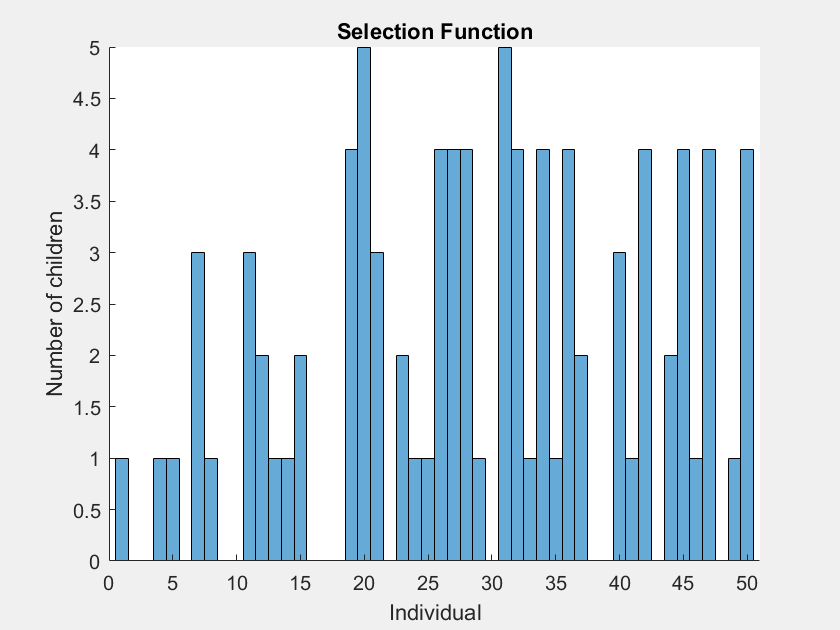

% Pass fixed parameters to objfun
objfun = @(x)objectiveFcn(x,a);

% Set nondefault solver options
options = optimoptions("gamultiobj","FunctionTolerance",0.01,"Display",...
    "iter","PlotFcn","gaplotselection");

% Solve
[solution,objectiveValue] = gamultiobj(objfun,nVar,[],[],[],[],x0,x1,[],[],...
    options);


% Clear variables
clearvars objfun options

## Results

`Optimize` saves the solution to the workspace variable `solution`, and saves the objective function value at the solution to the workspace variable `objectiveValue`. You can see and modify these variable names at the top of the `Optimize` task.

View these variables.

solution

solution =    24.1421  478.7178    0.3138
   16.0470  345.5118    0.3158
   20.8169  436.1933    0.3551
   13.1226  202.1565    0.3340
   22.7766  442.5905    0.3497
   12.8670  157.2958    0.3309
   24.1421  478.7182    0.3138
   13.0766  314.1547    0.3311
   14.0381  422.7661    0.3168
   17.3468  431.3239    0.3418


objectiveValue

objectiveValue =     0.0001    0.0253
    0.0001    0.0028
    0.0001    0.0040
    0.0002    0.0006
    0.0001    0.0042
    0.0002    0.0000
    0.0001    0.0253
    0.0002    0.0012
    0.0001    0.0022
    0.0001    0.0033


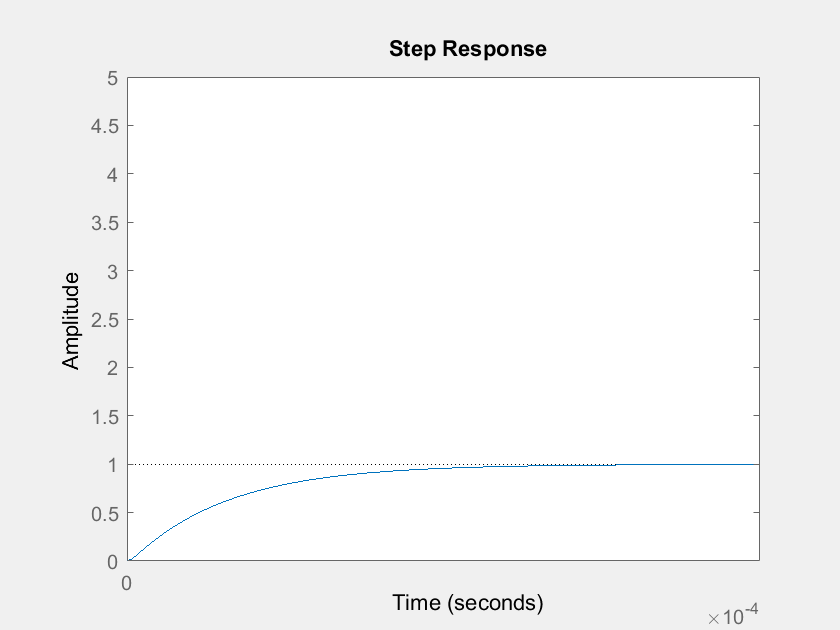


s = tf('s');
P_motor = K/(s*((J*s+b)*(L*s+R)+K^2));

kp = solution(size(solution,1),1);
ki = solution(size(solution,1),1);
kd = solution(size(solution,1),1);

C = pid(kp, ki, kd);

cl_loop = feedback(C*P_motor, 1);
step(cl_loop);


toc

Elapsed time is 2788.497816 seconds.


## Helper Functions — Local Functions

The following code creates the objective function. Modify this code for your problem.

function F = objectiveFcn(x,a)
s = tf('s');
P_motor = K/(s*((J*s+b)*(L*s+R)+K^2));

kp = x(1);
ki = x(2);
kd = x(3);

% disp(x);
X = ['kp ', kp, ' ki ', ki, ' kd ', kd];
disp(X);

C = pid(kp, ki, kd);

cl_loop = feedback(C*P_motor, 1);
dt = 0.01/2;
t = 0:dt:1;
y = step(cl_loop, t);

t_res = stepinfo(cl_loop);

ey = abs(1 - y);
est = abs(0.009 - t_res.SettlingTime);
f1 = sum(t'.*abs(ey)*dt);
%f2 = sum(t'.*abs(est)*dt);

F = [f1 est];

pause(0.5);
end

*Copyright 2020 The MathWorks, Inc.*